%% NMPC Swing-Up Control (Uses Existing Workspace Variables)
% WARNING: Do not use 'clear' before running this, or you will lose your motor params.

% =========================================================================
% 1. PACK PARAMETERS FROM WORKSPACE
% =========================================================================
% We assume the following are already defined in your workspace:
% m_pendulum, r, l, motor_k, motor_r, motor_j, motor_b, 
% gear_box_ratio, motor_effeciency, gear_box_effeciency

try
    % Mechanical primitives
    params.m = m_pendulum;
    params.r = r;
    params.l = l;
    params.g = 9.81;
    
    % Motor / Electrical primitives
    params.Kt = motor_k;
    params.Rm = motor_r;
    params.Kg = gear_box_ratio;
    params.eff = motor_effeciency * gear_box_effeciency;
    
    % Damping / Inertia
    params.J_arm = motor_j; % Base rotor inertia
    params.b_eq = motor_b;  % Base viscous friction
    
    % Derived Constants for Dynamics (matching your LQR logic)
    % 'a' from your LQR is the constant part of arm inertia
    params.J0 = params.J_arm + (params.m * params.r^2); 
    params.J_pend = (4/3) * params.m * params.l^2; % Your 'c' parameter
    
catch
    error('Missing variables! Run your LQR code first to define motor_k, r, l, etc.');
end

% =========================================================================
% 2. CONFIGURE NMPC CONTROLLER
% =========================================================================
nx = 4; % States: [theta(arm); alpha(pend); theta_dot; alpha_dot]
ny = 4; % Outputs: All states assumed measured
nu = 1; % Input: Voltage (V)

nlobj = nlmpc(nx, ny, nu);

Zero weights are applied to one or more OVs because there are fewer MVs than OVs.



% Sample time (must be fast enough for swing-up)
nlobj.Ts = 0.05; 
nlobj.PredictionHorizon = 20; 
nlobj.ControlHorizon = 5;

% Set the Nonlinear Dynamics Function
% We pass the 'params' struct to the function using an anonymous function handle
nlobj.Model.StateFcn = @(x,u) furutaDynamics(x, u, params);
nlobj.Model.IsContinuousTime = true; 

% Constraints
MaxVolts = 12; % Set this to your power supply limit (e.g., 12V or 24V)
nlobj.MV.Min = -MaxVolts;
nlobj.MV.Max = MaxVolts;

% Tuning Weights
% [Arm Angle, Pendulum Angle, Arm Velocity, Pend Velocity]
% We penalize deviation from Pendulum Angle=0 (Up) heavily.
nlobj.Weights.OutputVariables = [1 20 0.1 0.1]; 
nlobj.Weights.ManipulatedVariables = 0.1;       % Penalize voltage effort
nlobj.Weights.ManipulatedVariablesRate = 0.1;   % Penalize sudden spikes

% =========================================================================
% 3. SIMULATION LOOP
% =========================================================================
% Initial Condition: Pendulum DOWN (Alpha = pi)
x0 = [0; pi; 0; 0]; 
x = x0;
mv = 0; % Initial input

% Reference: Swing Up to 0 (Upright)
% [Arm=0, Pend=0, ArmVel=0, PendVel=0]
yref = [0 0 0 0]; 

Duration = 6; % seconds
Steps = Duration / nlobj.Ts;

% Arrays for plotting
xHistory = zeros(Steps, nx);
uHistory = zeros(Steps, nu);
tHistory = zeros(Steps, 1);

nloptions = nlmpcmoveopt;

fprintf('Simulating Nonlinear Swing-Up...\n');

Simulating Nonlinear Swing-Up...


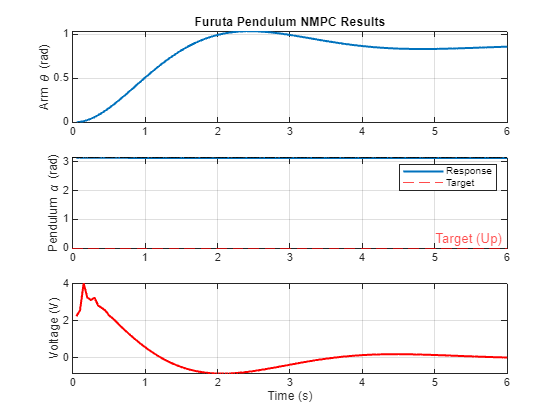


for k = 1:Steps
    % 1. Compute Optimal Control
    [mv, nloptions, ~] = nlmpcmove(nlobj, x, mv, yref, [], nloptions);
    
    % 2. Apply Control to Plant (Simulate real physics)
    % Using ode45 for high-fidelity integration of the nonlinear steps
    [~, x_new] = ode45(@(t, y) furutaDynamics(y, mv, params), [0 nlobj.Ts], x);
    x = x_new(end, :)'; 
    
    % 3. Store Data
    xHistory(k, :) = x';
    uHistory(k) = mv;
    tHistory(k) = k * nlobj.Ts;
end

% =========================================================================
% 4. PLOTTING
% =========================================================================
figure('Color','w');

subplot(3,1,1);
plot(tHistory, xHistory(:,1), 'LineWidth', 1.5); grid on;
ylabel('Arm \theta (rad)'); title('Furuta Pendulum NMPC Results');

subplot(3,1,2);
plot(tHistory, xHistory(:,2), 'LineWidth', 1.5); grid on;
yline(0, 'r--', 'Target (Up)'); 
yline(pi, 'k--', 'Start (Down)');
ylabel('Pendulum \alpha (rad)');
legend('Response', 'Target');

subplot(3,1,3);
plot(tHistory, uHistory, 'r', 'LineWidth', 1.5); grid on;
ylabel('Voltage (V)'); xlabel('Time (s)');



% =========================================================================
% 5. LOCAL DYNAMICS FUNCTION
% =========================================================================
function dxdt = furutaDynamics(x, u, p)
    % Unpack State
    theta     = x(1); % Arm Angle
    alpha     = x(2); % Pendulum Angle (0=Up, pi=Down)
    theta_dot = x(3);
    alpha_dot = x(4);
    
    % --- INERTIA MATRIX M(q) ---
    % M11: Effective Arm Inertia (varies with alpha)
    % M11 = J0 + m * l^2 * sin^2(alpha)
    M11 = p.J0 + (p.m * p.l^2) * (sin(alpha))^2;
    
    % M12: Coupling Inertia
    % M12 = m * r * l * cos(alpha)
    M12 = p.m * p.r * p.l * cos(alpha);
    
    % M22: Pendulum Inertia (Constant)
    M22 = p.J_pend;
    
    % Determinant of M
    det_M = M11*M22 - M12^2;
    
    % --- CORIOLIS & GRAVITY ---
    % C1 (Arm eq)
    C1 = -2 * (p.m * p.l^2) * sin(alpha) * cos(alpha) * theta_dot * alpha_dot ...
         + (p.m * p.r * p.l) * sin(alpha) * alpha_dot^2;
    
    % C2 (Pendulum eq)
    C2 = -(p.m * p.l^2) * sin(alpha) * cos(alpha) * theta_dot^2;
    
    % Gravity (acts only on Pendulum)
    G2 = -p.m * p.g * p.l * sin(alpha);
    
    % --- INPUT TORQUE & FRICTION ---
    % Calculate Motor Torque from Voltage u
    % Tau = (Kt * Kg * eff / Rm) * (V - Kb * Kg * theta_dot)
    % Assuming Back-EMF constant (Kb) is approx equal to Torque constant (Kt)
    motor_factor = (p.Kt * p.Kg * p.eff) / p.Rm;
    tau_motor = motor_factor * (u - p.Kt * p.Kg * theta_dot);
    
    % Viscous Friction (Arm)
    D1 = p.b_eq * theta_dot;
    
    % --- SOLVE ACCELERATIONS ---
    % eq1: M11*q1_dd + M12*q2_dd + C1 + D1 = tau
    % eq2: M12*q1_dd + M22*q2_dd + C2 + G2 = 0
    
    RHS1 = tau_motor - C1 - D1;
    RHS2 = -C2 - G2;
    
    % Inverse Mass Matrix solve (Cramer's rule for 2x2)
    theta_ddot = (M22 * RHS1 - M12 * RHS2) / det_M;
    alpha_ddot = (-M12 * RHS1 + M11 * RHS2) / det_M;
    
    dxdt = [theta_dot; alpha_dot; theta_ddot; alpha_ddot];
end
